# 802.11ac SEM (dB scale)

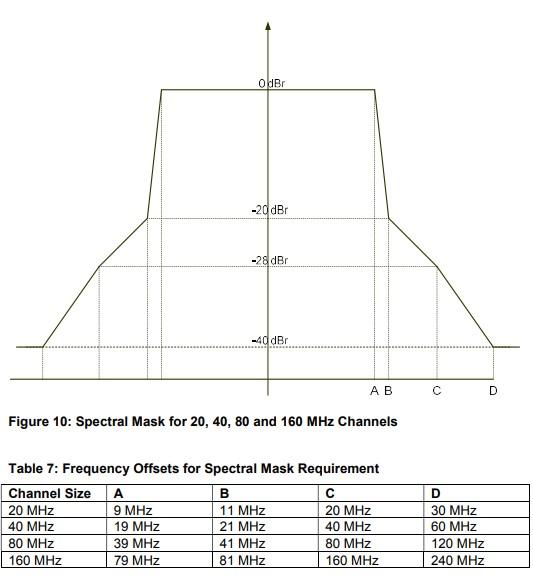

### Normalized frequency $f\in [-0.5, 0.5]$


$$f \text{(cycles/sample)} = \frac{F\text{(cycles/sec)}}{ F_s\text{(sampling rate)}} = \frac{F}{2B\text{(bandwidth)}}$$


### Definition of the 20 Mhz 802.11ac SEM function in $F$ (MHz)


$$\mathrm{SEM}(F) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |F| \leq 9\\
-10 |F| + 90 & \mbox{if } \quad 9\leq |F| \leq 11\\
-\frac{8}{9} |F| +(\frac{88}{9}-20) & \mbox{if } \quad 11\leq |F| \leq 20\\
-\frac{6}{5} |F| - 4 & \mbox{if } \quad 20\leq |F| \leq 30\\
-40 & \mbox{if } \quad |F| \geq 30\\
\end{array}\right.$$


### Definition of the 802.11ac SEM in $f, B$ (MHz)


$$\mathrm{SEM}(F) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |f| \leq \frac{9}{2B}\\
-10\cdot 2B \cdot |f| + 90 & \mbox{if } \quad \frac{9}{2B}\leq |f| \leq \frac{11}{2B}\\
-\frac{8}{9} \cdot 2B \cdot |f|+(\frac{88}{9}-20) & \mbox{if } \quad \frac{11}{2B}\leq |f| \leq \frac{20}{2B}\\
-\frac{6}{5} \cdot 2B \cdot |f| - 4 & \mbox{if } \quad \frac{20}{2B}\leq |f| \leq \frac{30}{2B}\\
-40 & \mbox{if } \quad |f| \geq \frac{30}{2B}\\
\end{array}\right.$$


function SEM = ac(delta_f, f_range, B, channel_size)
% Generate only the positive part
f = f_range(1):delta_f:f_range(2);
SEM = zeros(length(f), 1);

W = 2*B;

if channel_size == 20
    for idx = 1:length(f)
        if f(idx) < 9/W
            % freq: 0~9 MHz
            SEM(idx) = 0;
        elseif f(idx) < 11/W
            % freq: 9~11 MHz
            SEM(idx) = -10 * (f(idx)*W) + 90;
        elseif f(idx) < 20/W
            % freq: 11~20 MHz
            SEM(idx) = -(8/9) * (f(idx)*W) + (88/9 - 20);
        elseif f(idx) < 30/W
            % freq: 20~30 MHz
            SEM(idx) = -1.2 * (f(idx)*W) - 4;
        else
            % freq: >30 MHz
            SEM(idx) = -40;
        end
    end
elseif channel_size == 40
    for idx = 1:length(f)
        if f(idx) < 19/W
            % freq: 0~19 MHz
            SEM(idx) = 0;
        elseif f(idx) < 21/W
            % freq: 19~21 MHz
            SEM(idx) = -10 * (f(idx)*W) + 190;
        elseif f(idx) < 40/W
            % freq: 21~40 MHz
            SEM(idx) = -(8/19) * (f(idx)*W) + (168/19 - 20);
        elseif f(idx) < 60/W
            % freq: 40~60 MHz
            SEM(idx) = -0.6 * (f(idx)*W) - 4;
        else
            % freq: >60 MHz
            SEM(idx) = -40;
        end
    end
elseif channel_size == 80
    for idx = 1:length(f)
        if f(idx) < 39/W
            % freq: 0~39 MHz
            SEM(idx) = 0;
        elseif f(idx) < 41/W
            % freq: 39~41 MHz
            SEM(idx) = -10 * (f(idx)*W) + 390;
        elseif f(idx) < 80/W
            % freq: 41~80 MHz
            SEM(idx) = -(8/39) * (f(idx)*W) + (328/39 - 20);
        elseif f(idx) < 120/W
            % freq: 80~120 MHz
            SEM(idx) = -0.3 * (f(idx)*W) - 4;
        else
            % freq: >120 MHz
            SEM(idx) = -40;
        end
    end
elseif channel_size == 160
    for idx = 1:length(f)
        if f(idx) < 79/W
            % freq: 0~79 MHz
            SEM(idx) = 0;
        elseif f(idx) < 81/W
            % freq: 79~81 MHz
            SEM(idx) = -10 * (f(idx)*W) + 790;
        elseif f(idx) < 160/W
            % freq: 81~160 MHz
            SEM(idx) = -(8/79) * (f(idx)*W) + (648/79 - 20);
        elseif f(idx) < 240/W
            % freq: 160~240 MHz
            SEM(idx) = -(3/20) * (f(idx)*W) - 4;
        else
            % freq: >240 MHz
            SEM(idx) = -40;
        end
    end
end

% Generate the negative part
SEM = [flipud(SEM); SEM(2:end)];
end